%Ganancia del motor
K = 1;
%Masa del brazo [kg]
m = 11/1000;
%Gravedad
g = 9.81;
%Distancia del motor al CG del brazo
l = 130.2/1000;
%Momento de inercia [kg*m2]
Iz = 1.59/10000;
%Coeficiente de fricción
%-t*beta/(2*Iz)
beta = 0.2429*2*Iz;


## Datos experimentales

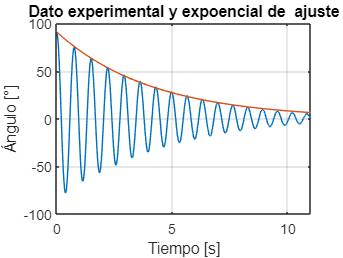

%Cargo el archivo
angle02 = load("Raw_angle02.txt");

%Hago una purga de datos
usefulA02 = angle02(308:1407); %1407
t02 = [1:1:length(usefulA02)]'*10/1000;
plot(t02, usefulA02, 'DisplayName', 'Datos exper')
title('Dato experimental y expoencial de  ajuste')
xlabel('Tiempo [s]')
ylabel('Ángulo [°]')
grid on
hold on
ajuste02 = 91.0473.*exp(-t02.*0.2414);
plot(t02, ajuste02, 'DisplayName', 'Ajuste expon')

## Ajustamos momento de inercia

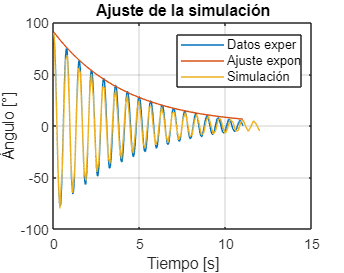

plot(out.simout.time, out.simout.data, 'DisplayName', 'Simulación')
title('Ajuste de la simulación')
xlabel('Tiempo [s]')
ylabel('Ángulo [°]')
legend